Signal Preprocessing 

First step in the System is Signal Preprocessing

We start by reading all the files 

%Reading all the Signals
    [raw_audio_1,Fs1]= audioread("Signals/Short_BBCArabic2.wav");
    [raw_audio_2,Fs2]= audioread("Signals/Short_FM9090.wav");
    [raw_audio_3,Fs3]= audioread("Signals/Short_QuranPalestine.wav"); 
    [raw_audio_4,Fs4]= audioread("Signals/Short_RussianVoice.wav");
    [raw_audio_5,Fs5]= audioread("Signals/Short_SkyNewsArabia.wav");

then we transform all the raw stereo audio into monochannel audio

 %Stereo Audio into Single Channel audio
    mono_audio_1=sum(raw_audio_1,2)/2;
    mono_audio_2=sum(raw_audio_2,2)/2;
    mono_audio_3=sum(raw_audio_3,2)/2;
    mono_audio_4=sum(raw_audio_4,2)/2;
    mono_audio_5=sum(raw_audio_5,2)/2;

then we pad all the signals with the same length getting our message

 %Pad all the signals
    message_length=max([length(mono_audio_1),length(mono_audio_2), ...
                        length(mono_audio_3),length(mono_audio_4) ...
                        ,length(mono_audio_5)]);
    message_1=padarray(mono_audio_1,message_length-length(mono_audio_1),0,'post');
    message_2=padarray(mono_audio_2,message_length-length(mono_audio_2),0,'post');
    message_3=padarray(mono_audio_3,message_length-length(mono_audio_3),0,'post');
    message_4=padarray(mono_audio_4,message_length-length(mono_audio_4),0,'post');
    message_5=padarray(mono_audio_5,message_length-length(mono_audio_5),0,'post');

then we get the Sampling Frequency and  Frequency domain

    %Sampling Frequency and Frequency domain
    Sampling_Freq=max([Fs1,Fs2,Fs3,Fs4,Fs5]);
    Freq=linspace(0,Sampling_Freq,message_length);

Then we get the spectrum for each message signal

    message_1_fft=fft(message_1);
    mag_spectrum_message_1=abs(message_1_fft)/message_length;
    message_2_fft=fft(message_2);
    mag_spectrum_message_2=abs(message_2_fft)/message_length;
    message_3_fft=fft(message_3);
    mag_spectrum_message_3=abs(message_3_fft)/message_length;
    message_4_fft=fft(message_4);
    mag_spectrum_message_4=abs(message_4_fft)/message_length;
    message_5_fft=fft(message_5);
    mag_spectrum_message_5=abs(message_5_fft)/message_length;

Then we plot all of them to Estimate the Bandwidth 

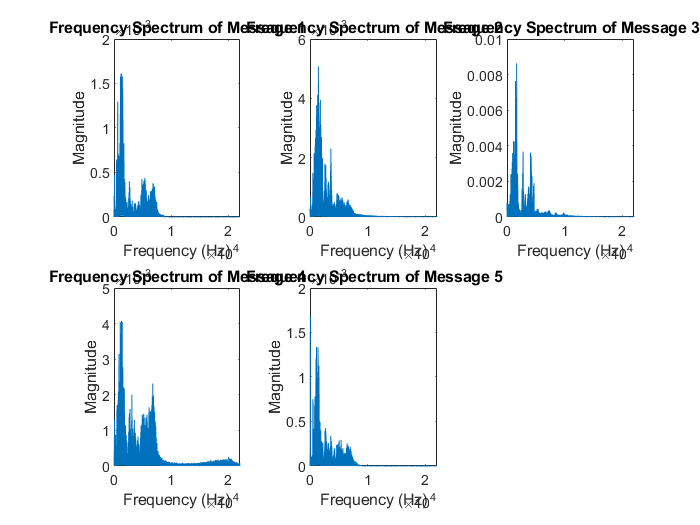

    subplot(2,3,1);
    plot(Freq(1:max_length/2), mag_spectrum_message_1(1:max_length/2));
    title('Frequency Spectrum of Message 1');
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
    subplot(2,3,2);
    plot(Freq(1:max_length/2), mag_spectrum_message_2(1:max_length/2));
    title('Frequency Spectrum of Message 2');
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
    subplot(2,3,3);
    plot(Freq(1:max_length/2), mag_spectrum_message_3(1:max_length/2));
    title('Frequency Spectrum of Message 3');
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
    subplot(2,3,4);
    plot(Freq(1:max_length/2), mag_spectrum_message_4(1:max_length/2));
    title('Frequency Spectrum of Message 4');
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
    subplot(2,3,5);
    plot(Freq(1:max_length/2), mag_spectrum_message_5(1:max_length/2));
    title('Frequency Spectrum of Message 5');
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');

We find that Base Band BandWidth **BBBW=10kHz**

Now we can optionally export the messages 

audiowrite("message_1.wav",message_1,Sampling_Freq);
audiowrite("message_2.wav",message_2,Sampling_Freq);
audiowrite("message_3.wav",message_3,Sampling_Freq);
audiowrite("message_4.wav",message_4,Sampling_Freq);
audiowrite("message_5.wav",message_5,Sampling_Freq);